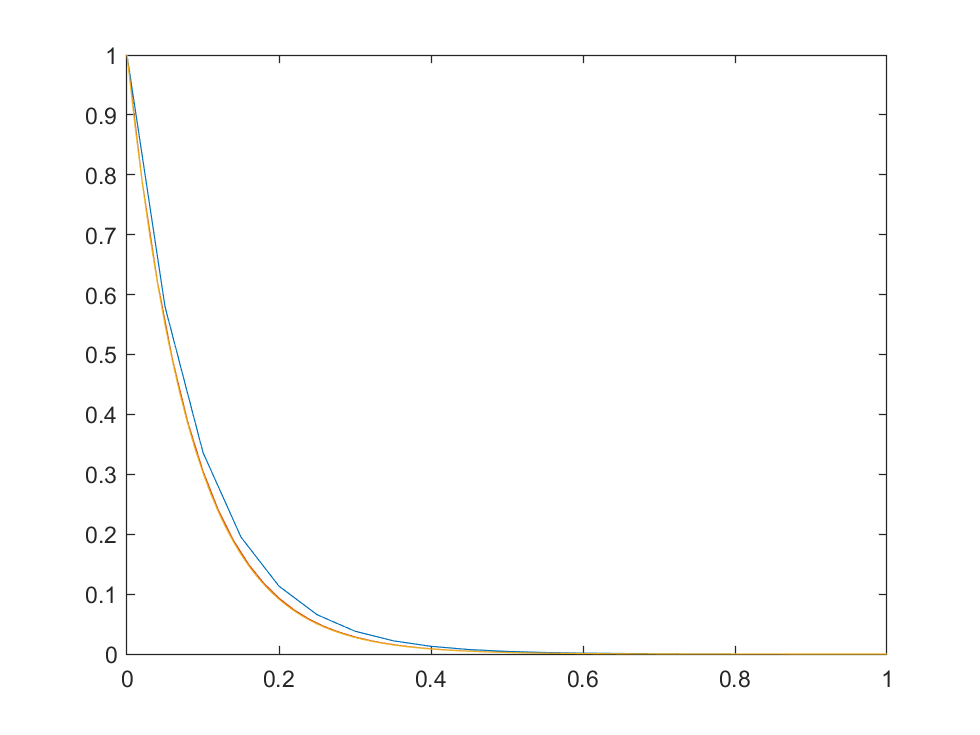

f =@(t,y) (-12*y);
F =@(t) (exp(-12*t));

a = 0;
b = 1;

alpha = 1;

N = [20,50,100];

y0 = RK2(f,a,b,alpha,N(1,1));
y1 = RK2(f,a,b,alpha,N(1,2));
y2 = RK2(f,a,b,alpha,N(1,3));

x0 = (b-a)/N(1,1);
x1 = (b-a)/N(1,2);
x2 = (b-a)/N(1,3);

t0 = a:x0:b;
t1 = a:x1:b;
t2 = a:x2:b;

t0 = t0';
t1 = t1';
t2 = t2';

plot(t0,y0,t1,y1,t2,y2);

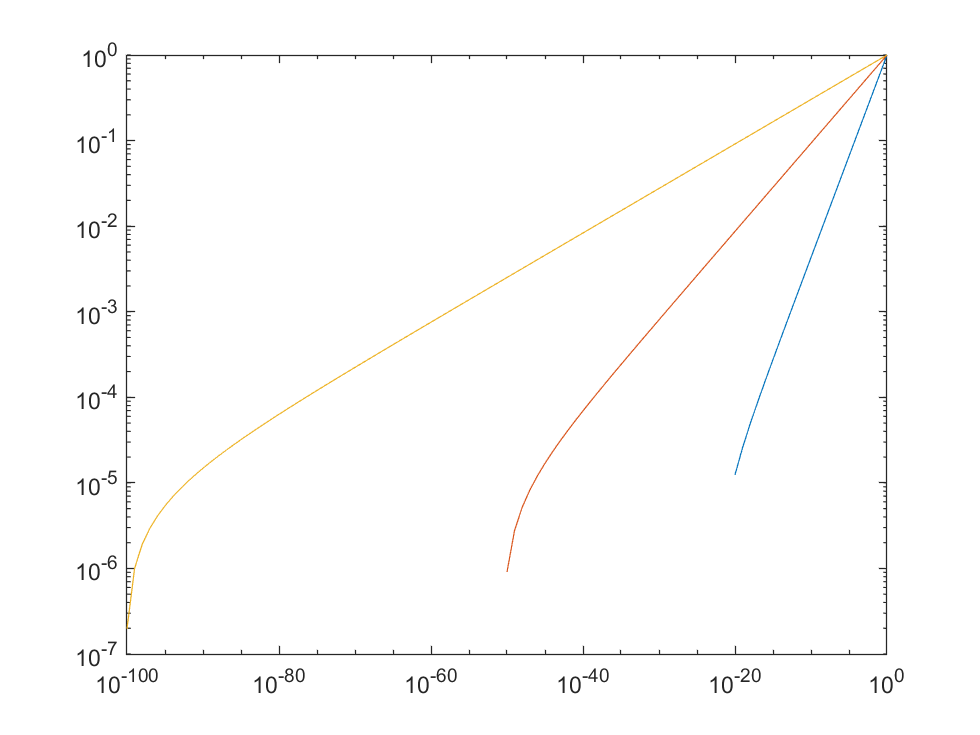


% the answer gets more accurate as the number of intervals increases

syms y(t)
eqn = diff(y,t) == (-12*y);
cond = y(0) == alpha;
ySol(t) = dsolve(eqn,cond);

eans = vpa(ySol(1));

h0 = ones(1,N(1,1)+1);
h1 = ones(1,N(1,2)+1);
h2 = ones(1,N(1,3)+1);

err0 = ones(1,N(1,1)+1);
err1 = ones(1,N(1,2)+1);
err2 = ones(1,N(1,3)+1);

% absolute error of 20 intervals
for i = 1:N(1,1)+1
    h0(1,i) = 10^(1-i);
    err0(1,i) = abs(eans-y0(i,1));
end

% absolute error of 50 intervals
for i = 1:N(1,2)+1
    h1(1,i) = 10^(1-i);
    err1(1,i) = abs(eans-y1(i,1));
end

% absolute error of 100 intervals
for i = 1:N(1,3)+1
    h2(1,i) = 10^(1-i);
    err2(1,i) = abs(eans-y2(i,1));
end

loglog(h0,err0);
hold on;
loglog(h1,err1);
loglog(h2,err2);
hold off;


Err = [err0(1,N(1,1)+1),err1(1,N(1,2)+1),err2(1,N(1,3)+1)];

% the error decreases as the number of intervals increases
% the method appears to be converging


function [y] = RK2(f,a,b,alpha,N)
    h = (b-a)/N;
    x = a:h:b;
    sx = size(x,2);
    y = ones(1,sx);
    y(1,1) = alpha;
    for i = 2:N+1
        k1 = h*f(x(1,i-1),y(1,i-1));
        k2 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k1/2));
        y(1,i) = y(1,i-1) + k2;
    end
    y = y';
end
